# Lecture 1 notes

This post is the first in a series on using MATLAB, specifically for electroencephalography (EEG) data analysis. It is based on a course module I taught at the University of Skövde in the fall of 2021, and I thought it would be fun to turn my lecture notes into a series of blog posts. The course module utilized the [following textbook](https://mitpress.mit.edu/books/introduction-event-related-potential-technique-second-edition): "An introduction to the event-related potential technique (2nd ed.)" by Steven Luck, which is recommended but not necessary reading for these posts. The [virtual ERP boot camp](https://courses.erpinfo.org/courses/Intro-to-ERPs) website is an excellent free alternative (or supplement) to the book.

These posts aim to provide a gentle introduction to programming with MATLAB - one of the most widely used software environments in neuroscience research generally - and guided instructions for working with EEG and event-related potential (ERP) data. My goal is that these posts will be helpful to both complete beginners and those with more experience. Therefore, throughout the series, I will provide additional links to various other resources that I have found useful when learning about MATLAB and EEG data analysis. 

These lectures assume that MATLAB, which is proprietary software, has been correctly installed and is working, which requires a MATLAB license. The free software [GNU Octave](https://www.gnu.org/software/octave/index) can perform many of the same features as MATLAB, so it is a viable option for those who do not have a MATLAB license. However, as I do not have any experience using Octave, I will not be covering it here.

## Getting started with MATLAB

MATLAB is short for **MAT**rix **LAB**oratory and is a high-level programming language and computing environment explicitly developed for scientists and engineers. MATLAB can be used in every step of an experiment, from programming the experimental stimuli and collecting data, to analysis and visualization. It contains a large number of built-in functions and is commonly used in all of neuroscience. MATLAB is owned and distributed by MathWorks, so it is not free software. MathWorks provide an introductory course, called [MATLAB onramp](https://se.mathworks.com/learn/tutorials/matlab-onramp.html), which I strongly recommend for beginners.

Let us start by taking a look at the MATLAB working environment:

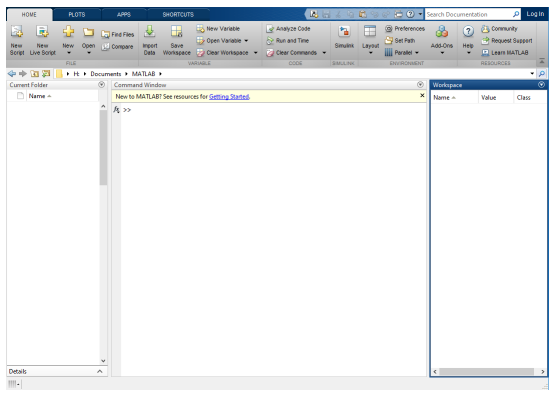

The desktop includes three main panels:

- **Current Folder:**  Access your files.

- **Command Windo**w:  Enter commands at the command line, indicated by the prompt (>>). 

- **Workspace:**  Explore data that you create or import from files.

### Command Window

When MATLAB is ready to receive a command from you, it displays >> in the command window.

You can use the command window as a calculator:

5+5

As you can see, MATLAB prints the answer as the output. Below are a few more examples, which also serves the purpose of introducing a few [mathematical operators](https://se.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html):  

5*5
5/5
5-5
5^2
((5-2)*(1+1))/(8-6)

While we are here, we can also check which toolboxes we have installed. To do so, simply type `ver` in the Command window:

ver

To make the most use of EEGLAB in later posts, you will ideally have the following four toolboxes installed:

- Image Processing Toolbox

- Optimization Toolbox

- Signal Processing Toolbox

- Statistics and Machine Learning Toolbox

If you have access to them through your license, but do not yet have them installed, you should re-install MATLAB with the toolboxes. If you do not have access to them, you will simply not have access to some of the EEGLAB functionality, but you will still be able to follow along.

### Workspace

This is where your data are saved. As we perform some calculation,

(4+3)-(9+8)

MATLAB automatically saves the answer in a **variable** called `ans` (short for answer).

This variable gets constantly updated, so we prefer to create our own variables (more on variables below).

var = 2*2
var2 = var*2

### Current Folder

To access data files with MATLAB, they need to be situated in a specific folder, or directory (your computer arranges all its files in a *directory structure* - the folders on your computer). Each of these folders have an "address", called its **path.** For example, the path to a certain directory might be something like C:\Program Files\MATLAB\R2021b.

MATLAB comes with a lot of built-in functions and toolboxes that we will explore later. These all reside inside the MATLAB installation folder. However, you generally do not want to save new files in this folder.

Type the command `matlabroot` in the command window to see where MATLAB is installed (the path to the installation folder). If this is also set as your current folder, you should definitely change it to some other folder.

matlabroot

You can see your current folder by typing `cd` in the command window, and you can list all files in the current folder by typing `ls`.

MATLAB automatically creates a personal folder for you upon installation, called the user work folder. Use `userpath` to see where this is. You likely have this as your current folder and, if not, you could change to it by clicking on "Browse for folder," which is the small folder icon immediately to the left of the address bar.

userpath

You can change it to whatever folder you prefer or simply keep it as is.

Finally, go to `Home > Set Path` and make sure that your current folder is added (Add folder...). This allows MATLAB to access your working directory. It is important to be able to change directories because the data and scripts you will be using later will likely be kept in different folders on your computer.

## Variables in MATLAB

Variables are the items we saw were stored in Matlab’s workspace. Different types of data can be stored in variables. In MATLAB, there are many different data types (also called [*classes*](https://se.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html)*)*. Every variable in MATLAB is an *array* – a structure that holds one or more values. For example, a special type of array is the matrix, an array of only numerical values (e.g., 5, 0, 3.21; more on matrices later). We will cover a several of these data types in the coming tutorials.

### Creating variables:

Consider the following line of code:

Y = 5 * (10+1);

- The equal sign `(=) `is called the assignment operator. It is used to define (create, declare) a variable in the workspace.

- Just as in mathematics, the parentheses (10+1) are calculated first.

- This right-hand side value is computed and assigned to the variable on the left.

- Ending a command with a semicolon (optional) keeps the output from being displayed in the Command Window.

**Let's create some variables**

Start by typing `clear `in the command window to clear the workspace. The command `clc` can be used to clear the command window.

MATLAB uses various different data types (or classes) to store variables. There are, in total, 16 data types in MATLAB. Examples are numeric, character, and logical values.

numeric = 5.78; % floating-point number
character = 'TextString';
logical = false;

These variables contain different types of data. Let's examine them by double-clicking on them in the workspace.

numeric is a numeric variable.

character is a character variable.

logical is a logical variable.

The command `whos` lists all the variables in the workspace, along with additional information.

whos

The numeric variable says double, not numeric. Why?

% num2 = single(numeric); % Convert to single. No need to remember this.
whos % List variables again

`single` and `double` are both subtypes of the numeric class. Double is the default numeric class. It takes up more memory but is more precise (think more decimal points).

You can use the Up-arrow in the command window to recall previous commands, and you can filter through previous commands by typing a few letters and then pressing the Up-arrow.

Another useful keyboard shortcut is Tab, which can be used to autocomplete a function, variable, or file name. For example, typ `fig` in the command windown and press Tab. This will give you a bunch of options to scroll through. If you add `u` (so `figu`) you should be able to hit Enter to autocomplete to `figure`.

In** Home >Preferences > Keyboard > Shortcuts**, you can see more keyboad shortcuts, and you can select whether to use the Windows Default or the Emacs Default (Mac and Linux). It is possible to use Windows Default on Mac or Linux.

You can name your MATLAB variables anything you want, as long as they start with a letter and contain only letters, numbers, and underscores ( _ ). Variable names are also case sensitive.

Some examples:

MyBestVariable = 5*5+5
My_Best_Variable = 10^2 +5
my_best_variable = 555 % Use the percentage sign to add a comment. MATLAB does not treat this as code to run.

Which of the following are valid variable names?

- sabo14

- bar jump

- cat_30

- 2dogs

Consider the following lines of code:

a = 5
b = 3
c = a + b
a = 4

What value will `c` take?

What about removing variables from the workspace?

clear MyBestVariable
clear all
clc

### Scalars, Vectors, and Matrices

As mentioned, all MATLAB variables are arrays, no matter what type of data. Scalar, vectors, and matrices are all numerical arrays, differing in the number of *dimensions*. A matrix, for example, is a 2-dimensional (columns and rows) array. The individual values in an array are called *elements*. 

**Matrix**                Values are stored in M rows and N columns (MxN)

**Row vector**        Values are stored in 1 row and N columns (1xN)

**Column vector**    Values are stored in N rows and 1 column (Nx1)

**Scalar **               A single value is stored (1x1)

matrix       = [1 2; 3 4]
rowVector    = [1 2 3 4]
columnVector = [1; 2; 3; 4]
scalar       = 5

Row vectors are created using square brackets [ ], in which you enter the numbers, separated by spaces, or commas or both.

These lines of code all produce the same 1 x 3 vector (pronounced 1-by-3).

myVector = [1,2,3]
myVector2 = [1 2 3]
myVector3 = [1, 2, 3]

Column vectors are created by separating the number with semicolons (;) instead of commas/spaces:

myNewVector  = [1;2;3] % 3x1 vector.
myNewVector2 = [1; 2; 3]

Matrices consist of both rows and columns. Commas/spaces are used to create the rows and semicolons to create the columns:

myMatrix = [1 2; 2 3] % 2x2 matrix

A matrix can even be empty (size 0x0):

emptyMatrix = []

Let us have a quick look at emptyMatrix in the Workspace and take a look. We can add elements manually to it if we would like. 

Let us overwrite the values in emptyMatrix.

What will be the dimensions of the matrix below?

emptyMatrix = [1, 2, 3; 4, 5, 6; 7, 8, 9];

### Data indexing

Because MATLAB stores everything as an array – even scalars are 1 x 1 arrays – accessing elements of an array is extermely useful when working with MATLAB. This process is called indexing, and it is used to access, extract, and modify subsets of arrays.

You can index a variable by typing the variable name followed by round brackets `()`. First we create a new vector:

clear
clc
myVector = [3 4 2 -8 -1 4 -4 6 0 -7] % 1x10 row vector

Below we extract the fourth element of the vector:

idx = myVector(4)

Let us move over to matrices. Scalars and vectors are, afterall, just smaller matrices.

clear
clc
newMatrix = [1, 2, 3; 4, 5, 6; 7, 8, 9]

Let us index the element in row 2 and column of `newMatrix`:

newIdx = newMatrix(2,3)

Have a look at the variable `anotherMatrix` below:

anotherMatrix = [3 5 2 4 0; 6 6 1 7 2; 1 1 3 2 8; 0 7 -2 4 3; -4 5 5 -1 9]

What command would you use to find the element of the 3rd row, first column?

Sometimes you want to extract whole rows or columns. Then you can use the colon character `(:)`, a symbol with several meanings in Matlab. During indexing, the colon refers to every element in a row or a column.

idx = anotherMatrix(2,:)

The command above extracts every element of row 2 and assigns it to a variable called `idx`.

Similarly, we can extract the last column:

idx2 = anotherMatrix(5,:)

What happens if you try to index an element that is not there?

idx3 = anotherMatrix(6,1)

### Summary

- A variable is declared by using the assignment operator `(=)`. For example, `X = 5` assigns the value 5 to variable X.

- MATLAB uses various different data types (or classes) to store variables. Examples are numbers, characters, and logical values.

- All variables in MATLAB are arrays.Scalars (1x1), vectors(Mx1 or 1xN), and matrices (MxN) are common numerical arrays. 

- Matrices can be indexed the following way: `variableName(row, column)`. Example: anotherMatrix(2,3) finds the element of the second row, third column of `anotherMatrix`.

- The best way to learn programming is by doing it. You will become better and better the more you practise. [MATLAB onramp](https://se.mathworks.com/learn/tutorials/matlab-onramp.html) is recommended.